url = 'https://fred.stlouisfed.org/';
c = fred(url);
format bank
c.DataReturnFormat = 'table';
c.DatetimeType = 'datetime';


%Fetch all available daily foreign exchange rates between the US dollar and the Euro using the series 'DEXUSEU'. The table d contains one row for the series. Each variable describes a piece of information about the series.

series = {'DEXUSEU'};
d = fetch(c,series)

d = 1×11 table
                    Title                       SeriesID                                Source                                          Release                      SeasonalAdjustment         Frequency                 Units                          DateRange                      LastUpdated                                                      Notes                                                    Data     
    ______________________________________    ____________    __________________________________________________________    ________________________________    ____________________________    __________    _____________________________    ____________________

y = []


y =

     []



x = 1:10

x =      1     2     3     4     5     6     7     8     9    10


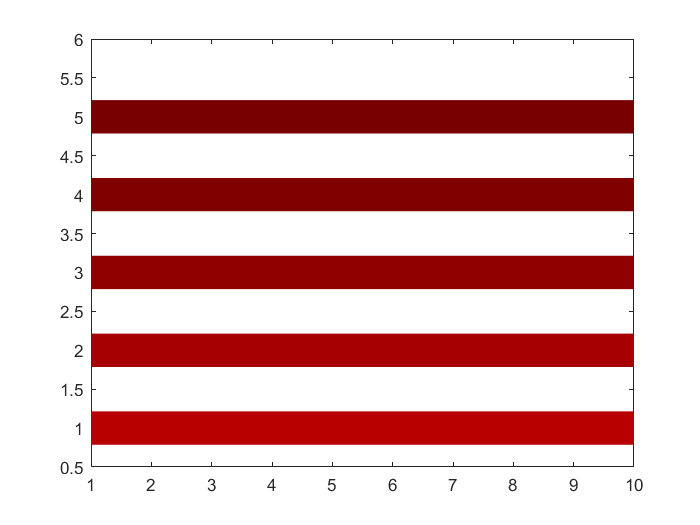

for i = 1:5
    y(i,:) = [repmat(i,[1 10])];
end

MyCol(1,:) = [0.72 0 0];
MyCol(2,:) = [0.65 0 0];
MyCol(3,:) = [0.57 0 0];
MyCol(4,:) = [0.5 0 0];
MyCol(5,:) = [0.47 0 0];

for i = 1:5
    plot(x,y(i,:),"LineWidth",20,"Color",MyCol(i,:))
    hold on
end
ylim([0.5 6])
hold off

f =uifigure

f =   Figure with properties:

      Number: []
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [489 343 560 420]
       Units: 'pixels'

  Show all properties


t = uitable(f)

t =   Table with properties:

                Data: []
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [20 20 300 300]
               Units: 'pixels'

  Show all properties


x = table(randn([10 1]))

x = 10×1 table
      Var1  
    ________

     0.44133
     -1.3981
    -0.25506
      0.1644
     0.74773
    -0.27305
      1.5763
    -0.48094
     0.32751
     0.66473


t =   Table with properties:

                Data: [10×1 table]
         ColumnWidth: 'auto'
      ColumnEditable: []
    CellEditCallback: ''
            Position: [20 20 300 300]
               Units: 'pixels'

  Show all properties


t.Data = x


[Sorted , indexes] = sort(x{:,:})

Sorted =          -1.40
         -0.48
         -0.27
         -0.26
          0.16
          0.33
          0.44
          0.66
          0.75
          1.58


indexes =           2.00
          8.00
          6.00
          3.00
          4.00
          9.00
          1.00
         10.00
          5.00
          7.00


[posro posco] = find(Sorted < 0)

posro =           1.00
          2.00
          3.00
          4.00


posco =           1.00
          1.00
          1.00
          1.00


[posrogr poscogr] = find(Sorted > 0)

posrogr =           5.00
          6.00
          7.00
          8.00
          9.00
         10.00


poscogr =           1.00
          1.00
          1.00
          1.00
          1.00
          1.00


RedCol = [linspace(0.8,0.4,10)' zeros([10 2])];
GreenCol = [ zeros([10 1]) linspace(0.8,0.4,10)' zeros([10 1])];

colinR = round(linspace(1,10,length(posro)))'

colinR =           1.00
          4.00
          7.00
         10.00


colinG = round(linspace(1,10,length(posrogr)))'

colinG =           1.00
          3.00
          5.00
          6.00
          8.00
         10.00


for i = 1:length(posro)
    
    s = uistyle("BackgroundColor",RedCol(colinR(i),:));
    addStyle(t,s,'cell',[indexes(posro(i)) 1]);
end

Unrecognized property 'FaceAlpha' for class 'matlab.ui.style.Style'.


for i = 1:length(posrogr)
    
    s = uistyle("BackgroundColor",GreenCol(colinG(i),:),"FaceAlpha", 0.5);
    addStyle(t,s,'cell',[indexes(posrogr(i)) 1]);
end


linspace(10,1,3)

ans =          10.00          5.50          1.00


a = [0.999 0.999 0.999 0.999; 0.99 0.99 0.99 0.99 ; 0.95 0.95 0.95 0.95]'

a =           1.00          0.99          0.95
          1.00          0.99          0.95
          1.00          0.99          0.95
          1.00          0.99          0.95


a = 1×1 cell array
    {'Normal'}


v = "Normal"

c = 'Normal'

b = 1×2 cell array
    {'Normal 99.9%'}    {'Normal 99%'}
